# Simple Double Pendulum Derivation

## Problem Setup

We will be solving for the equations of motion of a double simple pendulum in the presence of gravity and no other external forces.  The pendulum is defined as two masses ( $m_P$ and $m_Q$) connected by two massless, rigid links ($l_1$ from $O$ to $P$ and $l_2$ from $P$ to $Q$).  We define angle $\theta_1$ from the vertical to the first link and $\theta_2$ from the vertical to the second link.  We will use an inertial frame $\mathcal{I} = (O,\mathbf{e}_1,\mathbf{e}_2,\mathbf{e}_3)$ with $\mathbf{e}_1$ pointing in the direction of the gravity force (i.e., downwards) and $O$ being the pendulum's attchment point. We define frame $\mathcal{B} = (O,\mathbf{b}_1,\mathbf{b}_2, \mathbf{e}_3)$, with $\mathbf{b}_1
$ pointing along the direction of the first pendulum link and frame $\mathcal{C} = (O,\mathbf{c}_1,\mathbf{c}_2, \mathbf{e}_3)$, with $\mathbf{c}_1
$ pointing along the direction of the second pendulum link. 

We start by defining all of our variables:

syms m_P m_Q g l_1 l_2 F_1 F_2 'positive' %we are assuming these are all positive quantities
syms theta_1(t) theta_2(t) %we are explicitly defining the angles as functions of time
syms beta 'real' %useful variable for later

We start by setting up our frame transformations, encoded as direction cosine matrices. Note that $\mathcal{C}$ is a counterclockwise rotation from $\mathcal{B}$ by an angle $\theta_2 - \theta_1$

bCi = [cos(theta_1) sin(theta_1) 0;-sin(theta_1) cos(theta_1) 0;0 0 1]

$$bCi(t) = \left(\begin{array}{ccc} \cos\left(\theta_{1}\left(t\right)\right) & \sin\left(\theta_{1}\left(t\right)\right) & 0\\ -\sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

cCi = [cos(theta_2) sin(theta_2) 0;-sin(theta_2) cos(theta_2) 0;0 0 1]

$$cCi(t) = \left(\begin{array}{ccc} \cos\left(\theta_{2}\left(t\right)\right) & \sin\left(\theta_{2}\left(t\right)\right) & 0\\ -\sin\left(\theta_{2}\left(t\right)\right) & \cos\left(\theta_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

cCb = [cos(theta_2-theta_1) sin(theta_2-theta_1) 0;-sin(theta_2-theta_1) cos(theta_2-theta_1) 0;0 0 1]

$$cCb(t) = \left(\begin{array}{ccc} \cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right) & -\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right) & 0\\ \sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Next, we define the angular velocities of the two frames:

iWb = [0;0;diff(theta_1,t)] %angular velocity of B in I

$$iWb(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta_{1}\left(t\right) \end{array}\right)$$

iWc = [0;0;diff(theta_2,t)] %angular velocity of C in I

$$iWc(t) = \left(\begin{array}{c} 0\\ 0\\ \frac{\partial }{\partial t}\theta_{2}\left(t\right) \end{array}\right)$$

We will now compute the kinematics of $m_P$ in $\mathcal B$ frame components, using the transport equation:

r_PO_B = [l_1;0;0]

$$r\_PO\_B = \left(\begin{array}{c} l_{1}\\ 0\\ 0 \end{array}\right)$$

v_PO_B = diff(r_PO_B,t) + cross(iWb, r_PO_B) %inertial derivative of r_PO in B frame components

$$v\_PO\_B(t) = \left(\begin{array}{c} 0\\ l_{1}\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)\\ 0 \end{array}\right)$$

a_PO_B = diff(v_PO_B,t) + cross(iWb,v_PO_B) %inertial derivative of v_PO in B frame components

$$a\_PO\_B(t) = \left(\begin{array}{c} -l_{1}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ l_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)\\ 0 \end{array}\right)$$

We will now compute the kinematics of $m_Q
$ in $\mathcal C$ frame components, using the transport equation:

r_QP_C = [l_2;0;0]

$$r\_QP\_C = \left(\begin{array}{c} l_{2}\\ 0\\ 0 \end{array}\right)$$

v_QP_C = diff(r_QP_C,t) + cross( iWc,r_QP_C) %inertial derivative of r_PO in B frame components

$$v\_QP\_C(t) = \left(\begin{array}{c} 0\\ l_{2}\,\frac{\partial }{\partial t}\theta_{2}\left(t\right)\\ 0 \end{array}\right)$$

a_QP_C = diff(v_QP_C,t) + cross(iWc, v_QP_C) %inertial derivative of v_PO in B frame components

$$a\_QP\_C(t) = \left(\begin{array}{c} -l_{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\\ l_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)\\ 0 \end{array}\right)$$

What we actually want is the inertial acceleration of $Q$ with respect to $O$ - we can get this by adding the acceleration we've derived (with respect to $P$) to $P$'s acceleration with respect to $O$.  The only problem is that these are currently expressed in components of two different frames.  We'll use our DCM to convert the $\mathcal C$ frame components to $\mathcal B$ components:

a_QO_B = a_PO_B + transpose(cCb)*a_QP_C

$$a\_QO\_B(t) = \begin{array}{l} \left(\begin{array}{c} l_{2}\,\sigma_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)-l_{1}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}-l_{2}\,\sigma_{2}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\\ l_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+l_{2}\,\sigma_{1}\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+l_{2}\,\sigma_{2}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right) \end{array}$$

We can now apply Newton's second law to each mass.  We start by collecting all the forces.  Since we put all of our accelerations in $\mathcal B$ frame components, we'll do the same for the forces:

F_P = bCi*[m_P*g;0;0] + [-F_1;0;0] + transpose(cCb)*[F_2;0;0]

$$F\_P(t) = \left(\begin{array}{c} F_{2}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)-F_{1}+g\,m_{P}\,\cos\left(\theta_{1}\left(t\right)\right)\\ -F_{2}\,\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)-g\,m_{P}\,\sin\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

F_Q = bCi*[m_Q*g;0;0] + transpose(cCb)*[-F_2;0;0]

$$F\_Q(t) = \left(\begin{array}{c} g\,m_{Q}\,\cos\left(\theta_{1}\left(t\right)\right)-F_{2}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)\\ F_{2}\,\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)-g\,m_{Q}\,\sin\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

We formulate the vector equations of motion by subtracting the left and righthand sides of Newton's second law, such that all these equations should equal zero

eomP = m_P*a_PO_B - F_P

$$eomP(t) = \left(\begin{array}{c} -l_{1}\,m_{P}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+F_{1}-F_{2}\,\cos\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)-g\,m_{P}\,\cos\left(\theta_{1}\left(t\right)\right)\\ l_{1}\,m_{P}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+F_{2}\,\sin\left(\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\right)+g\,m_{P}\,\sin\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

eomQ = m_Q*a_QO_B - F_Q

$$eomQ(t) = \begin{array}{l} \left(\begin{array}{c} F_{2}\,\cos\left(\sigma_{2}\right)-m_{Q}\,\left(l_{1}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}-l_{2}\,\sin\left(\sigma_{2}\right)\,\sigma_{3}+l_{2}\,\cos\left(\sigma_{2}\right)\,\sigma_{1}\right)-g\,m_{Q}\,\cos\left(\theta_{1}\left(t\right)\right)\\ m_{Q}\,\left(l_{1}\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)+l_{2}\,\sin\left(\sigma_{2}\right)\,\sigma_{1}+l_{2}\,\cos\left(\sigma_{2}\right)\,\sigma_{3}\right)-F_{2}\,\sin\left(\sigma_{2}\right)+g\,m_{Q}\,\sin\left(\theta_{1}\left(t\right)\right)\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\\ \sigma_{2}=\theta_{1}\left(t\right)-\theta_{2}\left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right) \end{array}$$

These outputs are symbolic functions.  To index them, we need to make them into ordinary symbolic objects

eomP = eomP(t);
eomQ = eomQ(t);
eoms = subs([eomP(1:2); eomQ(1:2)],theta_2 - theta_1, beta)

$$eoms = \begin{array}{l} \left(\begin{array}{c} -l_{1}\,m_{P}\,\sigma_{2}+F_{1}-F_{2}\,\cos\left(\beta \right)-g\,m_{P}\,\cos\left(\theta_{1}\left(t\right)\right)\\ l_{1}\,m_{P}\,\sigma_{4}-F_{2}\,\sin\left(\beta \right)+g\,m_{P}\,\sin\left(\theta_{1}\left(t\right)\right)\\ F_{2}\,\cos\left(\beta \right)-m_{Q}\,\left(l_{1}\,\sigma_{2}+l_{2}\,\cos\left(\beta \right)\,\sigma_{1}+l_{2}\,\sin\left(\beta \right)\,\sigma_{3}\right)-g\,m_{Q}\,\cos\left(\theta_{1}\left(t\right)\right)\\ F_{2}\,\sin\left(\beta \right)+m_{Q}\,\left(l_{1}\,\sigma_{4}-l_{2}\,\sin\left(\beta \right)\,\sigma_{1}+l_{2}\,\cos\left(\beta \right)\,\sigma_{3}\right)+g\,m_{Q}\,\sin\left(\theta_{1}\left(t\right)\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta_{2}\left(t\right)\\ \sigma_{4}=\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right) \end{array}$$

We will now let MATLAB solve the algebraic expressions for us.  To do so, we need to replace the second derivative terms with dummy variables

syms th1dd th2dd beta
scalar_eoms = solve(subs(eoms,[diff(theta_1,t,t),diff(theta_2,t,t)],[th1dd,th2dd]),...
    [th1dd,th2dd,F_1,F_2])

scalar_eoms = struct with fields:
    th1dd: (l_2*m_Q*sin(beta)^3*diff(theta_2(t), t)^2 - g*m_P*sin(theta_1(t))*cos(beta)^2 - g*m_P*sin(theta_1(t))*sin(beta)^2 - g*m_Q*sin(theta_1(t))*sin(beta)^2 + g*m_Q*cos(theta_1(t))*cos(beta)*sin(beta) + l_2*m_Q*cos(beta)^2*sin(beta)*diff(theta_2(t…
    th2dd: -(sin(beta)*(l_1*m_P*diff(theta_1(t), t)^2 + l_1*m_Q*diff(theta_1(t), t)^2 + g*m_P*cos(theta_1(t)) + g*m_Q*cos(theta_1(t)) + l_2*m_Q*cos(beta)*diff(theta_2(t), t)^2))/(l_2*(m_P*sin(beta)^2 + m_Q*sin(beta)^2 + m_P*cos(beta)^2))
      F_1: (m_P*(l_1*m_P*cos(beta)^2*diff(theta_1(t), t)^2 + l_1*m_Q*cos(beta)^2*diff(theta_1(t), t)^2 + l_2*m_Q*cos(beta)^3*diff(theta_2(t), t)^2 + l_1*m_P*sin(beta)^2*diff(theta_1(t), t)^2 + l_1*m_Q*sin(beta)^2*diff(theta_1(t), t)^2 + g*m_P*cos(theta…
      F_2: (m_P*m_Q*(l_2*cos(beta)^2*diff(theta_2(t), t)^2 + l_2*sin(beta)^2*diff(theta_2(t), t)^2 + l_1*cos(beta)*diff(theta_1(t), t)^2 + g*cos(theta_1(t))*cos(beta)))/(m_P*sin(beta)^2 + m_Q*sin(beta)^2 + m_P*cos(beta)^

simplify(scalar_eoms.th1dd)

$$ans = \frac{g\,m_{Q}\,\sin\left(2\,\beta +\theta_{1}\left(t\right)\right)-g\,m_{Q}\,\sin\left(\theta_{1}\left(t\right)\right)-2\,g\,m_{P}\,\sin\left(\theta_{1}\left(t\right)\right)+2\,l_{2}\,m_{Q}\,\sin\left(\beta \right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}+l_{1}\,m_{Q}\,\sin\left(2\,\beta \right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}}{l_{1}\,\left(2\,m_{P}+m_{Q}-m_{Q}\,\cos\left(2\,\beta \right)\right)}$$

simplify(scalar_eoms.th2dd)

$$ans = -\frac{\sin\left(\beta \right)\,\left(l_{1}\,m_{P}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+l_{1}\,m_{Q}\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+g\,m_{P}\,\cos\left(\theta_{1}\left(t\right)\right)+g\,m_{Q}\,\cos\left(\theta_{1}\left(t\right)\right)+l_{2}\,m_{Q}\,\cos\left(\beta \right)\,{\left(\frac{\partial }{\partial t}\theta_{2}\left(t\right)\right)}^{2}\right)}{l_{2}\,\left(m_{Q}\,{\sin\left(\beta \right)}^{2}+m_{P}\right)}$$

And now, we can numerically integrate assuming state $z = \left[\theta_1, \dot{\theta}_1, \theta_2, \dot\theta_2\right]^T$

syms th1 dth1 th2 dth2


dz = simplify([dth1;subs(scalar_eoms.th1dd,[beta, theta_1, diff(theta_1,t), theta_2, diff(theta_2,t)], [th2-th1, th1, dth1, th2, dth2]);...
    dth2; subs(scalar_eoms.th2dd,[beta, theta_1, diff(theta_1,t), theta_2, diff(theta_2,t)], [th2-th1, th1, dth1, th2, dth2])])

$$dz = \begin{array}{l} \left(\begin{array}{c} {\mathrm{dth}}_{1}\\ -\frac{g\,\left(2\,m_{P}\,\sin\left({\mathrm{th}}_{1}\right)+m_{Q}\,\sin\left({\mathrm{th}}_{1}\right)+m_{Q}\,\sin\left({\mathrm{th}}_{1}-2\,{\mathrm{th}}_{2}\right)\right)}{l_{1}\,\sigma_{1}}\\ {\mathrm{dth}}_{2}\\ \frac{g\,\left(\sin\left(2\,{\mathrm{th}}_{1}-{\mathrm{th}}_{2}\right)-\sin\left({\mathrm{th}}_{2}\right)\right)\,\left(m_{P}+m_{Q}\right)}{l_{2}\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,m_{P}+m_{Q}-m_{Q}\,\cos\left(2\,{\mathrm{th}}_{1}-2\,{\mathrm{th}}_{2}\right) \end{array}$$

f1 = matlabFunction(dz,'vars',{th1, dth1, th2, dth2, m_P, m_Q, l_1, l_2, g})

f1 = function_handle with value:
    @(th1,dth1,th2,dth2,m_P,m_Q,l_1,l_2,g)[dth1;-(g.*(m_P.*sin(th1).*2.0+m_Q.*sin(th1)+m_Q.*sin(th1-th2.*2.0)))./(l_1.*(m_P.*2.0+m_Q-m_Q.*cos(th1.*2.0-th2.*2.0)));dth2;(g.*(sin(th1.*2.0-th2)-sin(th2)).*(m_P+m_Q))./(l_2.*(m_P.*2.0+m_Q-m_Q.*cos(th1.*2.0-th2.*2.0)))]


In order to numerically integrate, we need a function that takes in the state vector and time as inputs, so we simply wrap another lambda function about the first one.  Alternatively, we could also write this function out to disk (see matlabFunction documentation for details on that).

l1= 1;
l2 = 0.75;
f2 = @(t,z) f1(z(1),z(2),z(3),z(4),4,4,l1, l2, 9.81)

f2 = function_handle with value:
    @(t,z)f1(z(1),z(2),z(3),z(4),4,4,l1,l2,9.81)


[T,Z] = ode45(f2,linspace(0,10,1000),[pi/2+0.1,-3,pi/2,0]);

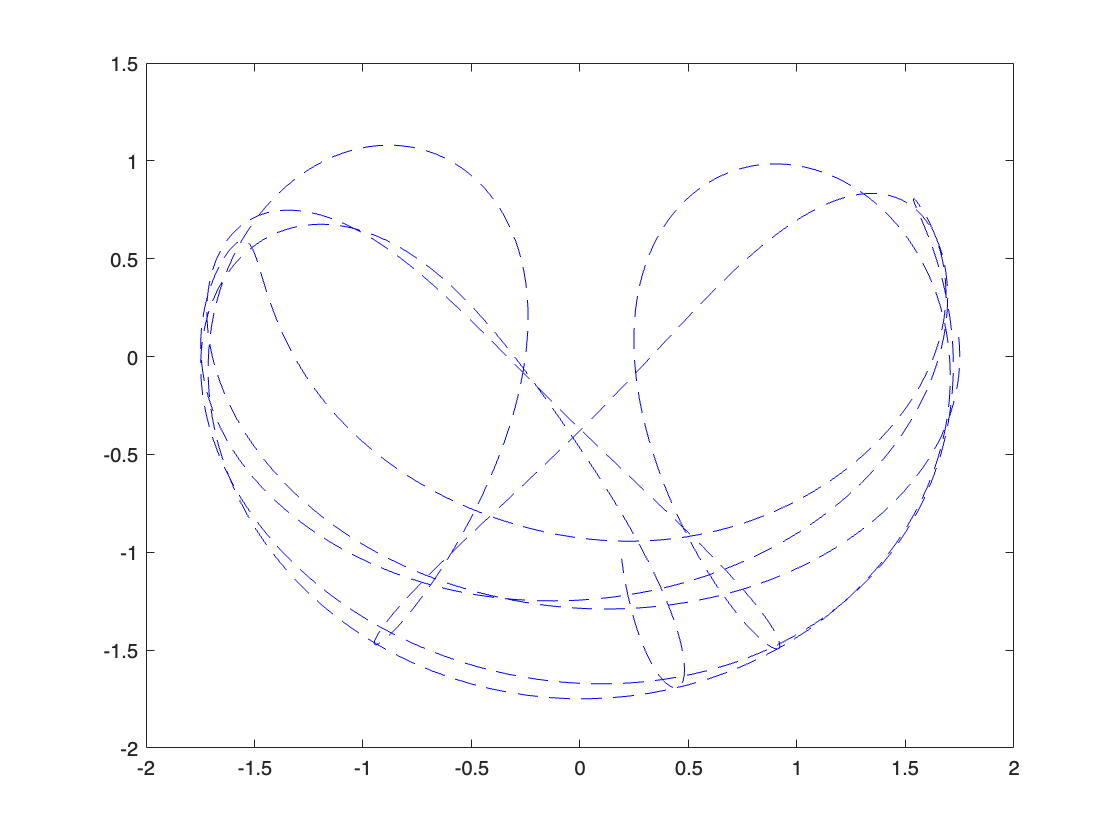

%figure out trajectories
th1 = Z(:,1);
th2 = Z(:,3);

%reconstruct the kinematics
r_poprime = [ l2*sin(th2),-l2*cos(th2)];
r_oprimeo = [ l1*sin(th1),-l1*cos(th1)];
r_po = r_poprime+r_oprimeo;
plot(r_po(:,1),r_po(:,2),'b--');